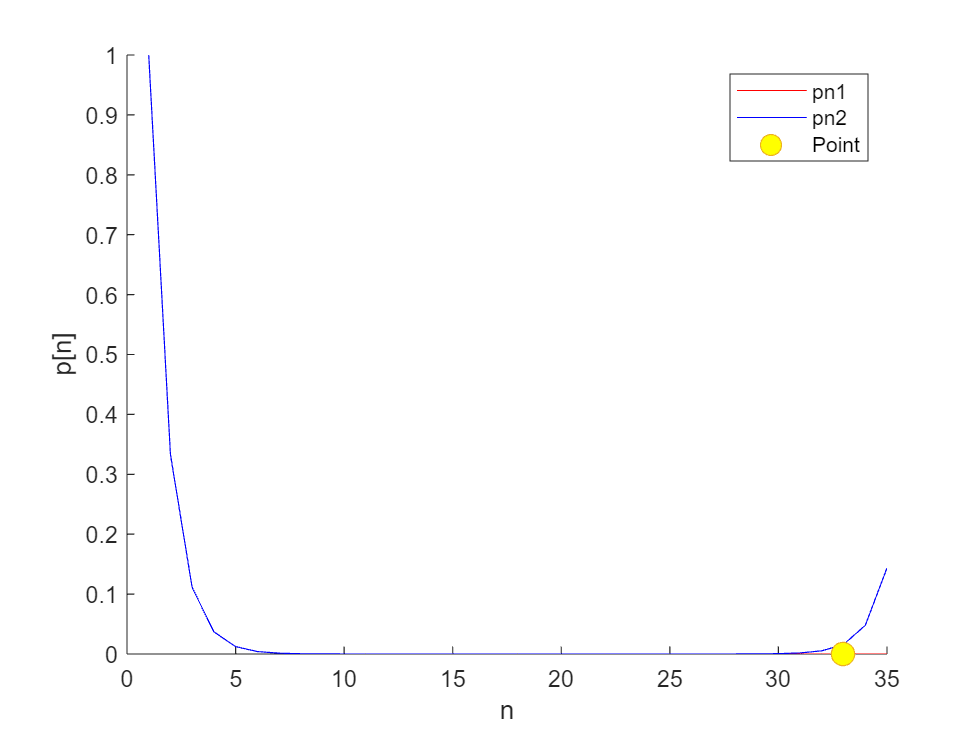

p0 = 1;
N = 35;
tolerance = 0.01;
flag2 = N + 1;

pn1 = zeros(1, N);
pn1(1) = p0;
for n = 1:N-1
    pn1(n+1) = (1/3) * pn1(n);
end

pn2 = zeros(1, N);
pn2(1) = p0;
pn2(2) = 1/3;
for n = 1:N-2
    pn2(n+2) = (10/3) * pn2(n+1) - pn2(n);
end

for n = 1:N
    if abs(pn1(n) - pn2(n)) > tolerance
        flag2 = n;
        break;
    end
end

hold on;
plot(1:N, pn1, 'r');
plot(1:N, pn2, 'b');
plot(flag2, pn1(flag2), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'yellow');

xlabel('n');
ylabel('p[n]');
legend('pn1','pn2','Point');